# Lab 06

# Sunspot Challenge – Open-Ended Lab

### Name: M. Shees Abbas

### ID: ma11212

## Task 1

## The main challenge of this lab is to extract the measured sunspots data year wise from 1700-2025 using MATLAB in .csv and .mat format. 

1) How did you find the data? 

i found the data at this [https://www.sidc.be/SILSO/datafiles](https://www.sidc.be/SILSO/datafiles) website, it contains the data collected by the Royal observatory of Belgium, it is  collected in the form of Yearly mean total sunspot number from (1700-now)

2) How was it downloaded? 

I download it from chrome using this link https://www.sidc.be/SILSO/INFO/snytotcsv.php in the form of CSV

3) How did you convert the data to .mat and .csv format?

raw = readmatrix('C:\Users\ma11212\University-work\SNS\Lab 6\SN_y_tot_V2.0 (1).csv', 'Delimiter', ';');
year = floor(raw(:,1));
sunspots = raw(:,2);
save('sunspots.mat', 'year', 'sunspots');
T = table(year, sunspots, 'VariableNames', {'Year', 'SunspotNumber'});
writetable(T, 'sunspots.csv');

so we first extracted the coloumns of year and sunspots numbers from the downloaded CSV file using readmatrix() then we separated that data into two arrays and then we used save() to make .mat file out of them and writetable() to make .csv file out of it the reason we made a new .csv file is becasue the orginal file had additional data with the year and sunspots that why we made a new file with only those two coloumns 

4) At the end of this Lab create a folder of your name populate it with your .m/.mlx file and Sunspots measured data (in .mat and .csv format) and submit it in the .m/.mlx file submission tab. 

## Task 2:

### **a)**

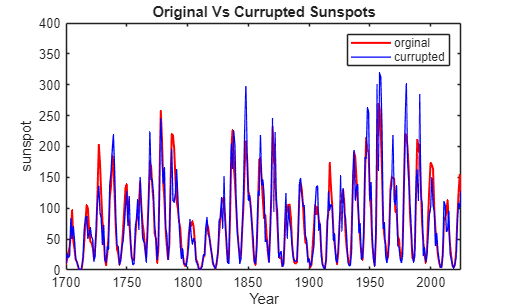

N = length(sunspots);
V = 0.5 + rand(N,1);

currupted = sunspots .* V;

figure;
plot(year, sunspots, "R",LineWidth=1.5)
hold on;
plot(year, currupted, "B",LineWidth=1)
xlabel("Year");
ylabel("sunspot");
title("Original Vs Currupted Sunspots");
legend("orginal", "currupted");
hold off
axis([1700, 2025, 0, 400])

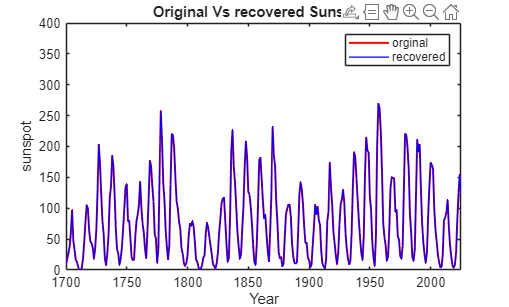





recovered = currupted ./ V;
figure;
plot(year, sunspots, "R",LineWidth=1.5)
hold on;
plot(year, recovered, "B",LineWidth=1)
xlabel("Year");
ylabel("sunspot");
title("Original Vs recovered Sunspots");
legend("orginal", "recovered");
hold off
axis([1700, 2025, 0, 400])